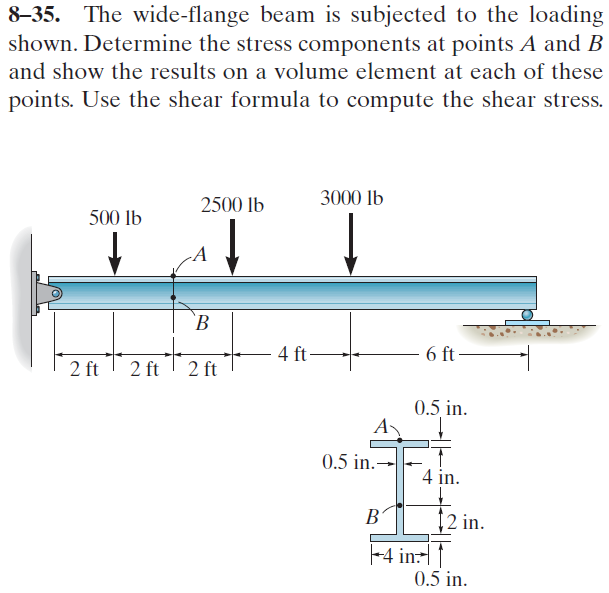

[https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-8-problem-35P-solution-9780136022305](https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-8-problem-35P-solution-9780136022305) 

# assumptions

u = symunit;
old_assum = assumptions;
clearassum;

# beam

b = beam;
b = b.add('reaction', 'force', 'R1', 0);
b = b.add('reaction', 'force', 'R2', 16*u.ft);
b = b.add('concentrated', 'force', -500*u.lbf, 2*u.ft);
b = b.add('concentrated', 'force', -2500*u.lbf, 6*u.ft);
b = b.add('concentrated', 'force', -3000*u.lbf, 10*u.ft);
b.L = 16*u.ft;

# section properties

yc = [0.5/2 0.5+2/2 0.5+2+4/2 0.5+2+4+0.5/2]*u.in;
Ac = [4*0.5 0.5*2 0.5*4 4*0.5]*u.in^2;
Ic = [4*0.5^3 0.5*2^3 0.5*4^3 4*0.5^3]/12*u.in^4;
[yn Qn In] = beam.neutral_axis(yc, Ac, Ic);
b.I = rewrite(sum(In), u.ft);

# solution

[y dy m v w rs ra hs ha] = b.elastic_curve('Mode', 'factor');

# elastic curve

y

$$y(x) = \left\{ \begin{array}{cl} -\frac{3240000\,x\,\left(828\,{\mathrm{ft}}^{2}-5\,x^{2}\right)}{77\,\text{E}}\,\frac{\mathrm{lbf}}{{\mathrm{ft}}^{4}} & \text{ if }x\leq 2\,\mathrm{ft}\\ \frac{648000\,\left(21\,x^{3}+24\,x^{2}\,\mathrm{ft}-4188\,x\,{\mathrm{ft}}^{2}+32\,{\mathrm{ft}}^{3}\right)}{77\,\text{E}}\,\frac{\mathrm{lbf}}{{\mathrm{ft}}^{4}} & \text{ if }x\in \left(2\,\mathrm{ft},6\,\mathrm{ft}\right]\\ \frac{648000\,\left(x^{3}+384\,x^{2}\,\mathrm{ft}-6348\,x\,{\mathrm{ft}}^{2}+4352\,{\mathrm{ft}}^{3}\right)}{77\,\text{E}}\,\frac{\mathrm{lbf}}{{\mathrm{ft}}^{4}} & \text{ if }x\in \left(6\,\mathrm{ft},10\,\mathrm{ft}\right]\\ -\frac{648000\,\left(x-16\,\mathrm{ft}\right)\,\left(23\,x^{2}-736\,x\,\mathrm{ft}+1772\,{\mathrm{ft}}^{2}\right)}{77\,\text{E}}\,\frac{\mathrm{lbf}}{{\mathrm{ft}}^{4}} & \text{ if }10\,\mathrm{ft}<x \end{array}\right.$$

dy

$$dy(x) = \left\{ \begin{array}{cl} -\frac{9720000\,\left(276\,{\mathrm{ft}}^{2}-5\,x^{2}\right)}{77\,\text{E}}\,\frac{\mathrm{lbf}}{{\mathrm{ft}}^{4}} & \text{ if }x\leq 2\,\mathrm{ft}\\ \frac{1944000\,\left(21\,x^{2}+16\,x\,\mathrm{ft}-1396\,{\mathrm{ft}}^{2}\right)}{77\,\text{E}}\,\frac{\mathrm{lbf}}{{\mathrm{ft}}^{4}} & \text{ if }x\in \left(2\,\mathrm{ft},6\,\mathrm{ft}\right]\\ \frac{1944000\,\left(x^{2}+256\,x\,\mathrm{ft}-2116\,{\mathrm{ft}}^{2}\right)}{77\,\text{E}}\,\frac{\mathrm{lbf}}{{\mathrm{ft}}^{4}} & \text{ if }x\in \left(6\,\mathrm{ft},10\,\mathrm{ft}\right]\\ -\frac{1944000\,\left(23\,x^{2}-736\,x\,\mathrm{ft}+4516\,{\mathrm{ft}}^{2}\right)}{77\,\text{E}}\,\frac{\mathrm{lbf}}{{\mathrm{ft}}^{4}} & \text{ if }10\,\mathrm{ft}<x \end{array}\right.$$

m

$$m(x) = \left\{ \begin{array}{cl} 3125\,x\,\mathrm{lbf} & \text{ if }x\leq 2\,\mathrm{ft}\\ 125\,\left(21\,x+8\,\mathrm{ft}\right)\,\mathrm{lbf} & \text{ if }x\in \left(2\,\mathrm{ft},6\,\mathrm{ft}\right]\\ 125\,\left(x+128\,\mathrm{ft}\right)\,\mathrm{lbf} & \text{ if }x\in \left(6\,\mathrm{ft},10\,\mathrm{ft}\right]\\ -2875\,\left(x-16\,\mathrm{ft}\right)\,\mathrm{lbf} & \text{ if }10\,\mathrm{ft}<x \end{array}\right.$$

v

$$v(x) = \left\{ \begin{array}{cl} 3125\,\mathrm{lbf} & \text{ if }x\leq 2\,\mathrm{ft}\\ 2625\,\mathrm{lbf} & \text{ if }x\in \left(2\,\mathrm{ft},6\,\mathrm{ft}\right]\\ 125\,\mathrm{lbf} & \text{ if }x\in \left(6\,\mathrm{ft},10\,\mathrm{ft}\right]\\ -2875\,\mathrm{lbf} & \text{ if }10\,\mathrm{ft}<x \end{array}\right.$$

w

$$w(x) = 0$$

# reactions and hinges

ra

$$ra = \left(\begin{array}{cc} R_{1} & 3125\,\mathrm{lbf}\\ R_{2} & 2875\,\mathrm{lbf} \end{array}\right)$$

ha

 
ha =
 
Empty sym: 0-by-2
 


# shear and moment diagram

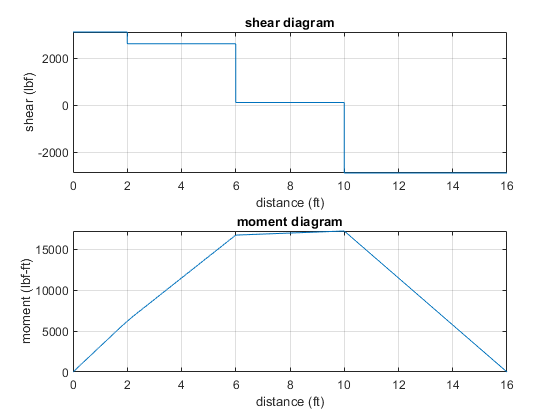

beam.shear_moment(m, v, [0 b.L], {'lbf' 'ft'});

# stresses at point A

% ---------------------------
% bending stress
M_a = m(4*u.ft);
y_a = yn;
b.I = rewrite(b.I, u.in);
sigma_a = rewrite(-M_a*y_a/b.I, u.psi);
sigma_a_vpa = vpa(sigma_a, 6) %#ok<NASGU> 

$$sigma\_a\_vpa = -9409.09\,\mathrm{psi}$$

% ---------------------------
% shear stress
tau_a = sym(0)

$$tau\_a = 0$$

% ---------------------------

# stresses at point B

% ---------------------------
% bending stress
M_b = m(4*u.ft);
y_b = 2.5*u.in-yn;
sigma_b = rewrite(-M_b*y_b/b.I, u.psi);
sigma_b_vpa = vpa(sigma_b, 6) %#ok<NASGU> 

$$sigma\_b\_vpa = 2688.31\,\mathrm{psi}$$

% ---------------------------
% shear stress
V_b = v(4*u.ft);
Q_b = sum(Qn(3:4));
t_b = 0.5*u.in;
tau_b = rewrite(V_b*Q_b/(b.I*t_b), u.psi);
tau_b_vpa = vpa(tau_b, 5) %#ok<NASGU> 

$$tau\_b\_vpa = 869.32\,\mathrm{psi}$$

% ---------------------------

# clean up

addvar(y);
assume(old_assum);
clear old_assum;
clear sigma_a_vpa;
clear sigma_b_vpa;
clear tau_b_vpa;